# Solving for the 3-D Orientation Distribution Function

Sections 5.2.2 and 5.3.2 discuss solutions for the orientation distribution function $\psi(\mathbf{p})$ in three dimensions.  This script shows solutions for both the standard Folgar-Tucker model and for anisotropic rotary diffusion (ARD) models.

## Folgar-Tucker Model

The governing equation for the Folgar-Tucker model is 


$$\frac{D \psi}{D t} = - \nabla_s \cdot (\psi \dot{\mathbf{p}}) + C_I \, \dot{\gamma} \; \nabla_s^2 \psi  $$


The function `solvePsi3D` solves this equation, setting up a finite difference grid in $\theta$ and $\phi$.  The grid looks like this:

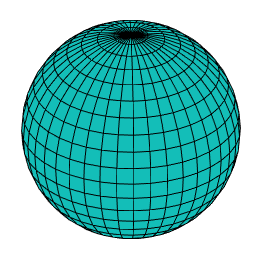

The code finds the flux of probability $\mathbf{q}$ at the boundaries of each cell, and uses them to update the cell values of $\psi$ to the next time step.  Only half the sphere is modeled, since $\psi(\mathbf{p}) = \psi(-\mathbf{p})$.  Once $\psi$ has been found at each time step, one can calculate additional quantities like the orientation tensor $\mathbf{A}$.  

Here is a calculation that reproduces Fig. 5.7 from the book:

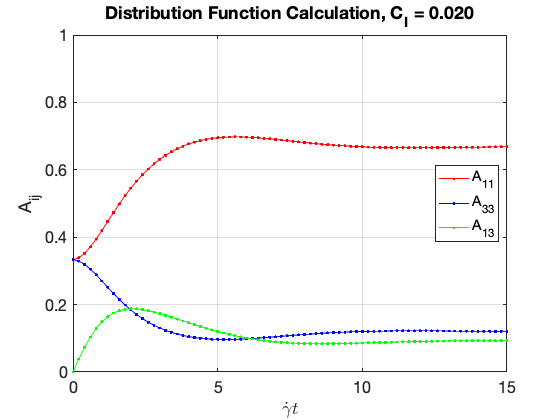

% Input parameters
L = zeros(3);
L(1,3) = 1;            % Velocity gradient tensor, 1-3 simple shear flow
CI = 0.02;             % Interaction coefficient
xi = 1;                % Particle shape factor
tEnd = 15;             % Ending time
dtIn = 0.2;            % Time step for returning results
ntheta = 45;           % Grid points in theta
nphi   = ntheta;       % Grid points in phi; nphi = ntheta is standard
Co = 1;                % Courant number
scheme = 'power';      % Use power-law upwinding

% Solve for the distribution function
[t, Av, ~, psi, ~, ~, px, py, pz] = ...
           solvePsi3D(L, CI, xi, tEnd, dtIn, ntheta, nphi, Co, scheme);

% Plot tensor results
figure
plot(t, Av(1,:), 'r.-', t, Av(3,:), 'b.-', t, Av(5,:), 'g.-')
set(gca, 'FontSize', 16)
xlabel('$\dot{\gamma} t$', 'Interpreter', 'LaTeX')
ylabel('A_{ij}')
legend('A_{11}', 'A_{33}', 'A_{13}', 'Location', 'East')
grid on
box on
axis([0 tEnd 0 1])
title(sprintf('Distribution Function Calculation, C_I = %5.3f', CI))

It is worth trying different values of $C_I$, and even changing $\xi$, to see how that affects the solution.  For smaller $C_I$ values or $\xi < 1$ you may want to increase the value of `tEnd`.  

Similar to `solvePsi2D`, a Courant number can be set to control the time stepping in the calculation.  Both central differencing and power-law upwinding are available.  The latter is useful for smaller values of $C_I$ or when using a coarser grid, though this code is fairly efficient.  

We can also plot the actual distribution functions, as in Fig.~5.6.  Here's the code to do that, with many of the gritty details hidden in `surfPsi3D`.  We'll let Matlab auto-scale the color axis here, though the plots in the book use a common scale.  Adjust `plottime` and re-run this section to see the distribution function at different times.

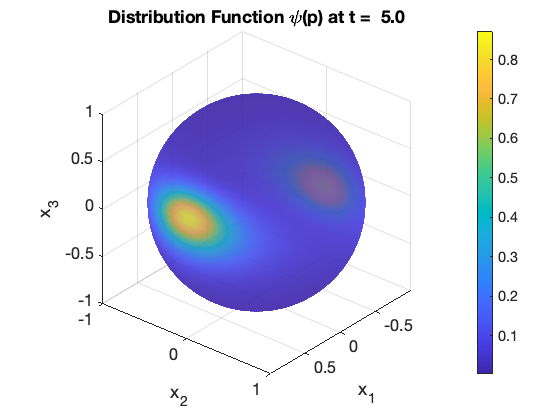

% Plot the distribution function at a selected time
plottime = 5;
iplot = find(t >= plottime, 1);  % Index of the time step to plot
figure
% Create the plot:
hs = surfPsi3D(px, py, pz, psi(:,iplot)); % hs is a handle to the surf
set(hs, 'FaceAlpha', 0.7);                % Adjusts transparency

% Dress up the plot
view(130, 30)
set(gca, 'FontSize', 16)
xlabel('x_1')
ylabel('x_2')
zlabel('x_3')
colorbar
title(sprintf('Distribution Function \\psi(p) at t = %4.1f', t(iplot)))

Note the use of the FaceA`lpha` property of the `surf` object to adjust its transparency.

## ARD Models

A separate function, `solvePsiARD`, is used to find $\psi (\mathbf{p}, t)$ for various anisotropic rotary diffusion models.  The syntax is similar to `solvePsi3D`, but in the input arguments $C_I$ is replaced by `diffModel` and `diffParam`, which specify the ARD model and its parameters.

Here we'll use the MRD model and parameters from Table 5.3.

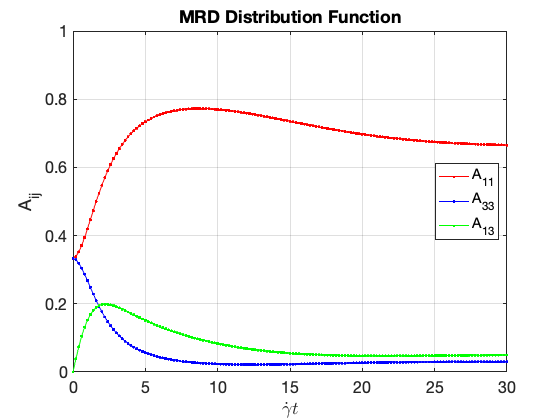

% Input parameters
L = zeros(3);
L(1,3) = 1;            % Velocity gradient tensor, 1-3 simple shear flow
xi = 1;                % Particle shape factor
tEnd2 = 30;             % Ending time
dtIn = 0.2;            % Time step for returning results
ntheta = 45;           % Grid points in theta
nphi   = ntheta;       % Grid points in phi; nphi = ntheta is standard
Co = 1;                % Courant number
scheme = 'power';      % Use power-law upwinding

% ARD model
diffModel = 'M';                    % MRD model
diffParam = [0.0270, 0.5, 0.0281];  % CI, D2, D3 (D1 = 1)

% Solve for the distribution function
[t2, Av2, ~, psi2, ~, ~, px, py, pz] = ...
    solvePsiARD(L, diffModel, diffParam, xi, ...
                tEnd2, dtIn, ntheta, nphi, Co, scheme);

% Plot tensor results
figure
plot(t2, Av2(1,:), 'r.-', t2, Av2(3,:), 'b.-', t2, Av2(5,:), 'g.-')
set(gca, 'FontSize', 16)
xlabel('$\dot{\gamma} t$', 'Interpreter', 'LaTeX')
ylabel('A_{ij}')
legend('A_{11}', 'A_{33}', 'A_{13}', 'Location', 'East')
grid on
box on
axis([0 tEnd2 0 1])
title('MRD Distribution Function')

This solution settles to a similar value of $A_{11}$ as the Folgar-Tucker calculation above, but has much lower values of $A_{33}$ and $A_{13}$.  

The same ARD models that are available in `Adot2` are also available in `solvePsiARD`.  

If you re-run this section, you will see that `solvePsiARD` takes much longer to run than `solvePsi3D`.  This is because all the coefficients in the finite difference equations must be re-calculated at each time step for an ARD model.  For the Folgar-Tucker model, `solvePsi3D` calculates the coefficients once and partially solves the equations (via a LU decomposition), so that each time step is very efficient.  

Here's what the ARD distribution function looks like at steady state (same code as above):

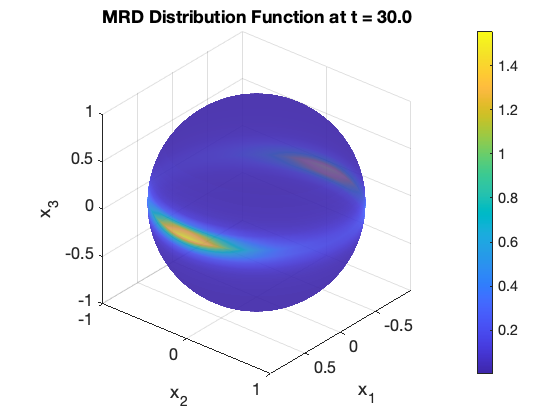

% Plot the distribution function at a selected time
plottime2 = 30;
iplot2 = find(t2 >= plottime2, 1);  % Index of the time step to plot
figure
% Create the plot:
hs = surfPsi3D(px, py, pz, psi2(:,iplot2)); % hs is a handle to the surf
set(hs, 'FaceAlpha', 0.7);                % Adjusts transparency

% Dress up the plot
view(130, 30)
set(gca, 'FontSize', 16)
xlabel('x_1')
ylabel('x_2')
zlabel('x_3')
colorbar
title(sprintf('MRD Distribution Function at t = %4.1f', t2(iplot2)))

Notice how the 'hot spot' of high orientation spreads more in the 2 direction than in the 3 direction, compared to the more equal spread with the Folgar-Tucker (isotropic rotary diffusion) model.    